## Energy Based Voice Detection: Static Threshold

### Read in Sound Data:

clear;
[d,s]= audioread('C:\DSP Project\clean_ness_speech.wav');
s

s = 48000

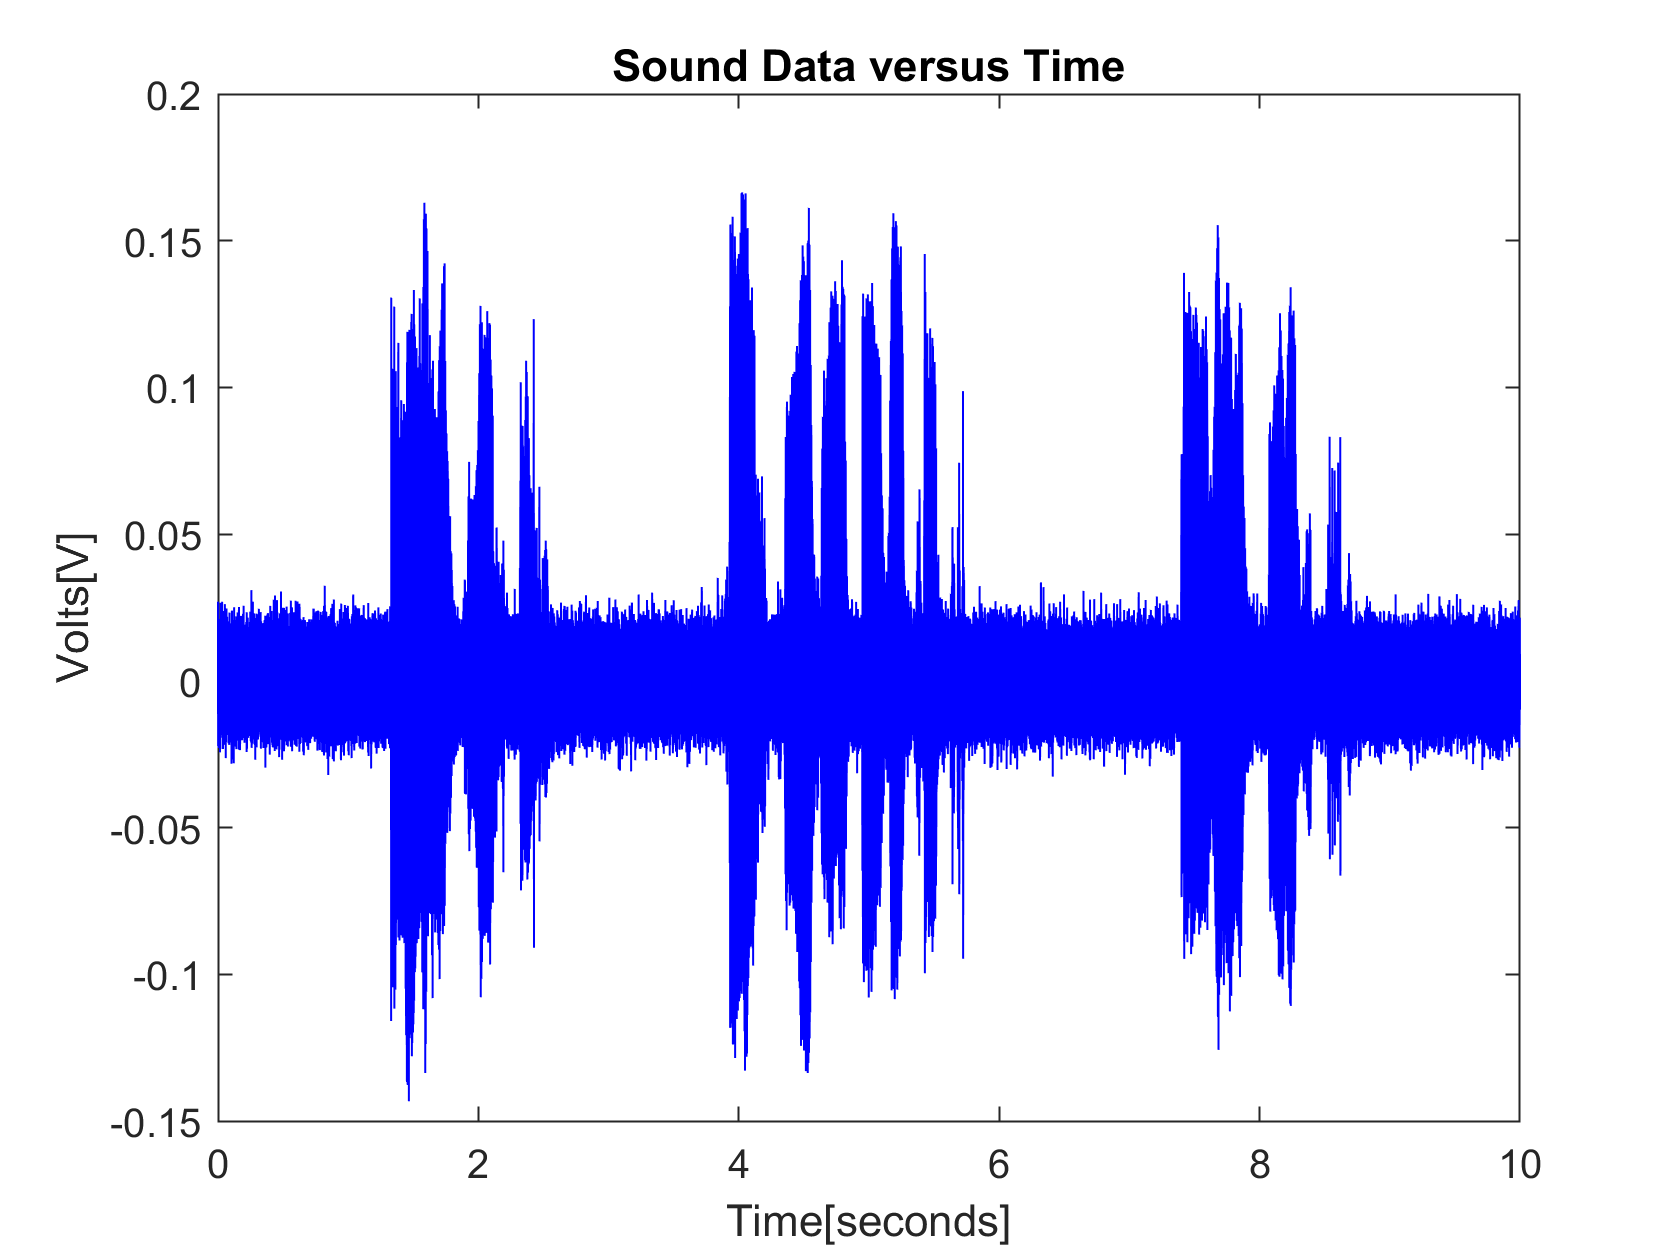

t = 0:1:length(d)-1;
t=t/s;
for i =1:1:length(t)-1
    if t(i)==10
        c =i;
    end
end 
figure()
d = d(1:c);
t = t(1:c);
%for white noisy signals
SNR=10; %set SNR
z=awgn(d,SNR,'measured');
d=z;

%for babble noise signals
% [d1, s1] = audioread('C:\DSP Project\babble.wav');
% d1 = interp(d1, 6);
% d1 = 0.1*d1;
% l=length(d1);
% d1(l+1)=0;
% n=d1+d';
% d=n;

%for car noise
% [d1, s1] = audioread('C:\DSP Project\car.wav');
% d1 = interp(d1, 6);
% d1 = 0.1*d1;
% l=length(d1);
% d1(l+1)=0;
% n=d1+d';
% d=n;

plot(t,d, 'b');
title('Sound Data versus Time')
xlabel('Time[seconds]');
ylabel('Volts[V]');

### Organise The Sound Data into Frames:

frame_length = 0.01;            %10ms per frame
n_frames = 10/frame_length;     %no. of frames in sound data

sample_per_frame =frame_length*s; 
last_samp = 1;

for k=1:1:n_frames
   new_d(:,k)= d(last_samp:last_samp+sample_per_frame) ;
   last_samp = last_samp + sample_per_frame;
end 

new_d(sample_per_frame+1,:)=[];
new_d(:,1)=[];      %where every column is 1 frame (10ms long)
                    %check if first column is all 0

### Get Energy Per Frame:

s_d = new_d.^2;                     %square each term
for i = 1:1:n_frames-1
   col = s_d(:,i);
   E(i) = sum(col)./sample_per_frame; %get Energy of each frame(column)
end

### Calculate the Threshold and Classify Sound Data:

thresh = E(1);              %noise threshold is just first frame energy
for i= 1:1:n_frames-1
    if thresh<E(i)
        s_frames(i) = 1;  %frame is speech
    else 
        s_frames(i)=0;      %frame is noise
    end
end

### Plot the Energy and Voice Detection:

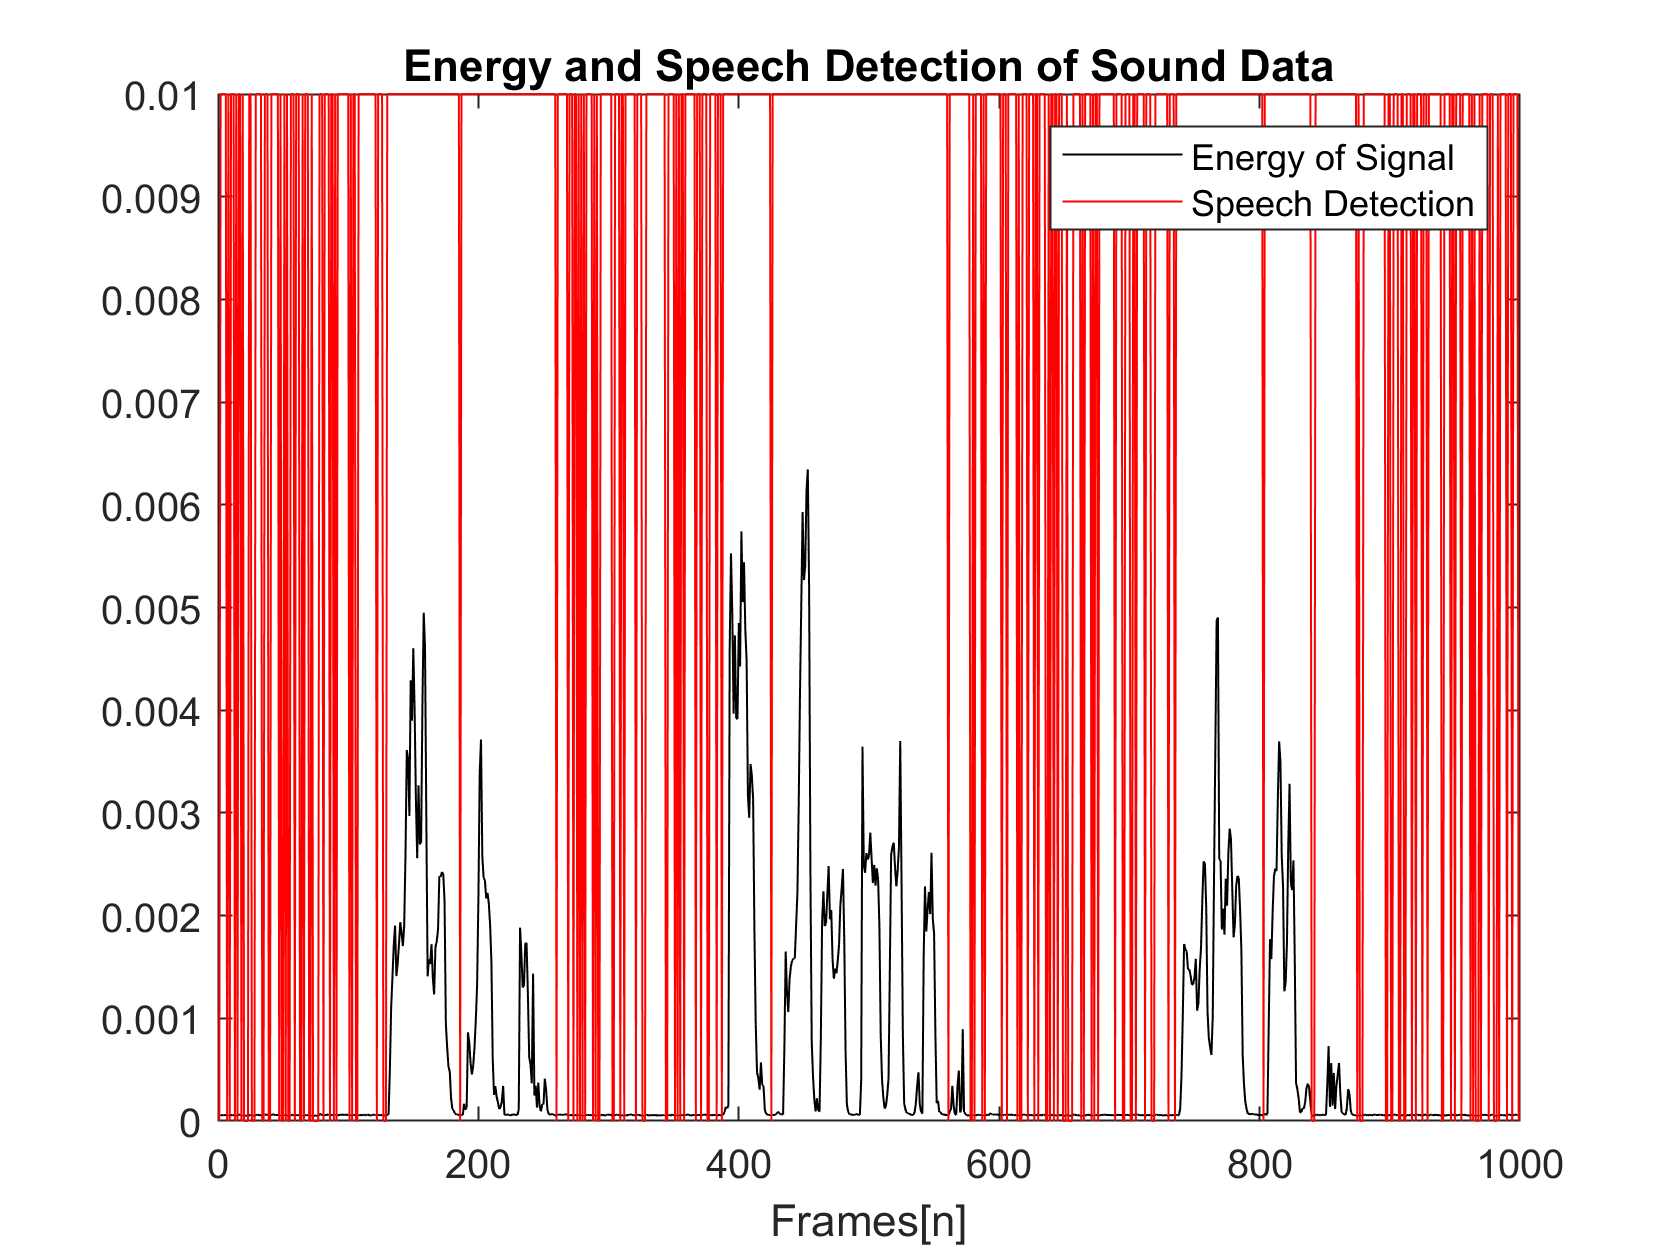

figure();
plot(E,'k')
hold on 
plot(0.01*s_frames,'r')
title('Energy and Speech Detection of Sound Data');
xlabel("Frames[n]");
legend("Energy of Signal","Speech Detection","Location" ,"northeast");

### Plot the Sound Data and Voice Detection:

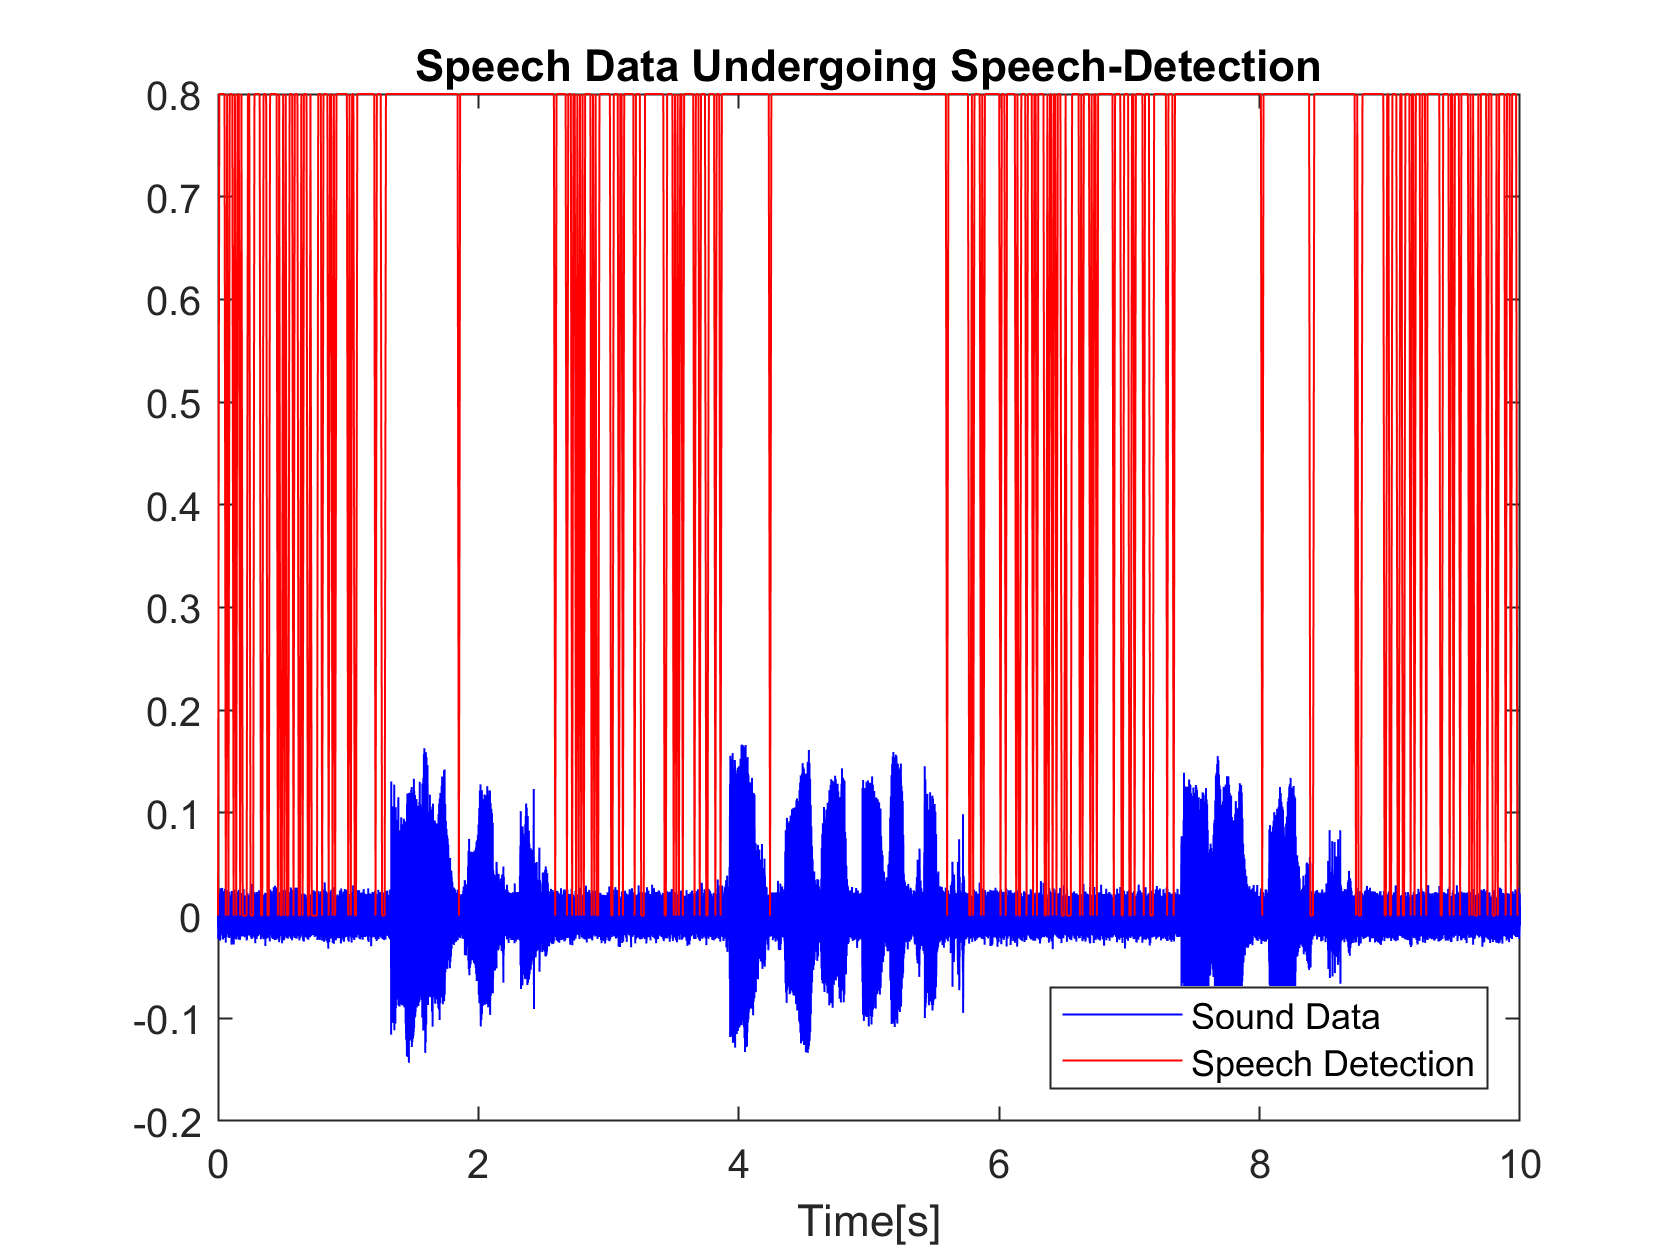

VAD_time(1)=0;
for i = 1:1:length(s_frames)-1
    VAD_time(i+1)= 0.01*i;
end
figure()
plot(t,d,'b')
hold on
plot(VAD_time,0.8.*s_frames, 'r')
title('Speech Data Undergoing Speech-Detection');
xlabel("Time[s]");

legend("Sound Data","Speech Detection","Location" ,"southeast");

## Find % accuracy

VAD_labelled(1:128) =0;
VAD_labelled(129:260)=1;
VAD_labelled(261:380) = 0;
VAD_labelled(381:603) = 1;
VAD_labelled(604:736) = 0;
VAD_labelled(737:893) = 1;
VAD_labelled(893:999) = 0;

% VAD_labelled2(1:181) = 0;
% VAD_labelled2(182:421) = 1;
% VAD_labelled2(422:476) = 0;
% VAD_labelled2(477:699) = 1;
% VAD_labelled2(700:709) = 0;
% VAD_labelled2(710:776) = 1;
% VAD_labelled2(777:825) = 0;
% VAD_labelled2(826:982) = 1;
% VAD_labelled2(983:999) = 0;

num_correct=0;
for i=1:1:999
    if s_frames(i)==VAD_labelled(i)
        num_correct=num_correct+1;
    end
end
num_correct

num_correct = 630

pc_correct = num_correct/999 * 100

pc_correct = 63.0631

## Make Verification Audio Clip

% l =0;
% for i = 1:1:length(VAD_labelled)
%     if s_frames(i) == 0
%         a(l+1:i*sample_per_frame) = 0;
%     else 
%         a(l+1:i*sample_per_frame) = 1;
%     end
%     l = length(a);
% end
% d_actual = d(sample_per_frame+2:end);
% new_a = d_actual.* a';
% figure();
% audiowrite('female_babble_static_energy.wav', new_a, s);
% [y, Fs] = audioread('female_babble_static_energy.wav');
% sound(y, Fs);